# Optimal Solver

clc;clear
N = 100

N = 100

r = 1.5

r = 1.5000

setup of the city locations and the sequence of cities. The sequence was chosen by hand and by a GA as shown in the other sections of the PDF.

cities = [8.5, 6.2, 3.5, 5.1, 4.0, 0.8, 2.4, 1.2, 1.8, 2.4; 4.2, 0.5, 9.0, 9.4, 4.9, 4.9, 3.4, 9.0, 3.7, 1.1];
sequence = [10, 2, 1, 4, 3, 8, 6, 9, 7, 5]

sequence =     10     2     1     4     3     8     6     9     7     5


start = [0; 0];
corners = [0, 10, 10, 0; 0, 0, 10, 10];
% sequence = [1 2 3 4 5 6 7 8 9 10];
cities_x = [0 cities(1, sequence)]

cities_x =          0    2.4000    6.2000    8.5000    5.1000    3.5000    1.2000    0.8000    1.8000    2.4000    4.0000


cities_y = [0 cities(2, sequence)]

cities_y =          0    1.1000    0.5000    4.2000    9.4000    9.0000    9.0000    4.9000    3.7000    3.4000    4.9000


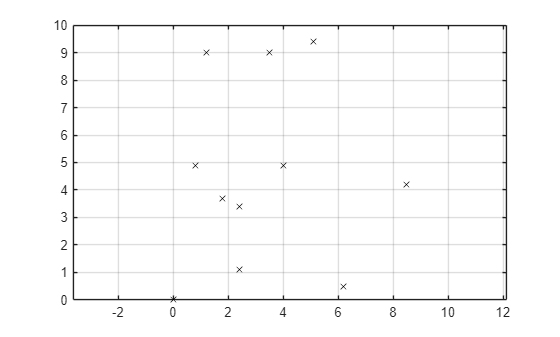


plot(cities_x, cities_y, "xk")
axis([0 10 0 10])
grid on
axis equal

## Setup functions for BPV4c:

Here are some of the functions that are used to set up the optimality solver. They are placed here just for convenience. When possible, they were generalized to accept any number of cities.

function H = Hamiltonian(s,r)
gamma = -(r/2)*s(7);
if abs(gamma)>1
    gamma = sign(gamma);
end
a = -(r/2)*s(8);
if abs(a)>1
    a = sign(a);
end
H = 1 + (1/r)*(gamma^2 + a^2) + s(5)*s(4)*cos(s(3)) + s(6)*s(4)*sin(s(3)) + s(7)*gamma + s(8)*a;
end

function ds = ODEMain(t, s, times, r)
for ii = 1:numel(times)
    ds(ii*8-7:ii*8, 1) = ODEs(t, s(ii*8-7:ii*8), r)*times(ii);
end
end

function ds = ODEs(~, s, r)
% s(1) = x, s(2) = y, s(3) = theta, s(4) = v
% s(5) = lambda_x, s(6) = lambda_y, s(7) = lambda_theta, s(8) = lambda_v

gamma = -(r/2)*s(7);
if abs(gamma)>1
    gamma = sign(gamma);
end

a = -(r/2)*s(8);
if abs(a)>1
    a = sign(a);
end
ds(1, 1) = s(4)*cos(s(3));
ds(2, 1) = s(4)*sin(s(3));
ds(3, 1) = gamma;
ds(4, 1) = a;
ds(5, 1) = 0;
ds(6, 1) = 0;
ds(7, 1) = s(5)*s(4)*sin(s(3))-s(6)*s(4)*cos(s(3));
ds(8, 1) = -s(5)*cos(s(3))-s(6)*sin(s(3));
end

Boundary condition function. This follows a similar format as shown in class to allow for any number of cities. We only ever ran it with 10 cities, so this was more an expediency to avoid writing all the boundary conditions than a necessity.

function con = bcfunc(so, sf, r, cities, start, times)
    % Initial conditions
    con(1) = so(1) - start(1);   % x(0) = 0
    con(2) = so(2) - start(2);   % y(0) = 0
    con(3) = so(7);              % lambda_theta(0) = 0
    con(4) = so(4);              % v(0) = 0

    % Interior arc connections and city constraints
    for i = 1:(length(times)-1)
        % continuity of x, y, theta, v
        con(9*i-4:9*i-1) = sf(1+8*(i-1):4+8*(i-1)) - so(8*i+1:8*i+4);

        % arc i ends exactly at city i
        con(9*i:9*i+1) = [
            sf(1+8*(i-1)) - cities(1,i);
            sf(2+8*(i-1)) - cities(2,i)
        ];

        % continuity of lambda_theta and lambda_v
        con(9*i+2:9*i+3) = sf(7+8*(i-1):8+8*(i-1)) - so(8*i+7:8*i+8);

        % Hamiltonian zero at the interior junction for this arc
        con(9*i+4) = Hamiltonian(sf(1+8*(i-1):8+8*(i-1)), r);
    end

    % Final arc conditions (arc m)
    lastCityIdx = length(times);  % = number of arcs = number of cities

    con(9*i+5) = sf(end-7) - cities(1,lastCityIdx); % x(tf) = last city
    con(9*i+6) = sf(end-6) - cities(2,lastCityIdx); % y(tf) = last city
    con(9*i+7) = sf(end-1);      % lambda_theta(tf) = 0
    con(9*i+8) = sf(end);        % lambda_v(tf) = 0
    con(9*i+9) = Hamiltonian(sf(end-7:end), r); % H(tf) = 0
end



## Hometopy Setup

To set up the problem, we first converted the Cartesian positions of the cities to polar coordinates that point from one city to another. When given the starting point and sequence, this allows us to easily apply rotational transformations to the cities and also enables straightforward conversion back to Cartesian coordinates for solving or plotting.

% arc_dist = dist2(cities_x, cities_y)
steps_end = polarSteps([cities_x; cities_y])

steps_end =     2.6401    3.8471    4.3566    6.2129    1.6492    2.3000    4.1195    1.5620    0.6708    2.1932
    0.4298   -0.1566    1.0146    2.1499   -2.8966    3.1416   -1.6680   -0.8761   -0.4636    0.7532



steps_start = [steps_end(1, :); steps_end(2, 1)*ones(1, length(steps_end))]

steps_start =     2.6401    3.8471    4.3566    6.2129    1.6492    2.3000    4.1195    1.5620    0.6708    2.1932
    0.4298    0.4298    0.4298    0.4298    0.4298    0.4298    0.4298    0.4298    0.4298    0.4298


difference_rad = steps_end(2, :) - steps_start(2, :)

difference_rad =          0   -0.5864    0.5849    1.7201   -3.3264    2.7118   -2.0978   -1.3058   -0.8934    0.3234


cartesian = polarSteps2cart([0 0], steps_start)

cartesian =          0    2.4000    5.8972    9.8577   15.5056   17.0049   19.0957   22.8406   24.2606   24.8704   26.8641
         0    1.1000    2.7029    4.5181    7.1067    7.7939    8.7522   10.4686   11.1194   11.3989   12.3127



% sum(steps_start(1, :))

ans = 29.5514


cities = cartesian(:, 2:end);
start = [0; 0];

solinit

## Initial Solution Guess

Since we are using the rotational hometopy method we have some liberties on how relaxed we can make the initial guess. As a test we assumed that the car had constant velocity. This allows for very easy interpolation of the x and y positions along the line. This also made most of the $\lambda$ easy to solve. We assumed that $\lambda_{\theta }$ and $\lambda_v$ are zero to satify the free BC at the cities. $\lambda_x$ and $\lambda_y$ were assumed to be constants and a trigonometric function of the initial angle. While we did assume that velocity is constant and equal to one for each position to allow for easy time to distance conversion, the initial BC of $v\left(0\right)=0$ was imposed explicitly to help convergence and satify the BCs. This explicit imposation of the initial velocty does mean that there is a non-physical, almost instant acceleration from $v\left(0\right)=0$ to $v\left(0^+ \right)=1$however this was a small enough problem as to not impede the initial solution.

% One "time" parameter per leg between points in "cities"
m = size(cities, 2);           % number of legs / arcs

% Use radial distances from the polar step representation as initial times
% (time ≈ distance when v ≈ 1)
T0 = steps_start(1, 1:m);      % 1×m, distances of each leg

Nmesh = 30;                    % mesh points for BVP4c
solinit.x = linspace(0, 1, Nmesh);
solinit.y = zeros(8*m, Nmesh);

for i = 1:m
    % start and end positions for arc i
    if i == 1
        p0 = start;            % [x0; y0] for first leg
    else
        p0 = cities(:, i-1);   % previous city
    end
    p1 = cities(:, i);         % target city for this leg

    dx = p1(1) - p0(1);
    dy = p1(2) - p0(2);

    dist = hypot(dx, dy);
    if dist < 1e-8
        theta_i = 0;
    else
        theta_i = atan2(dy, dx);   % heading for this leg
    end

    % We'll keep theta constant along the leg, and v ≈ 1
    % but enforce v(0) = 0 for the BC at t=0.
    v_const = 1;

    % Costates chosen so that H ≈ 0 when v = 1:
    % H = 1 + λ_x v cosθ + λ_y v sinθ
    % choose λ_x = -cosθ, λ_y = -sinθ, λ_θ = 0, λ_v = 0 ⇒ H = 1 - 1 = 0
    lambda_x  = -cos(theta_i);
    lambda_y  = -sin(theta_i);
    lambda_th = 0;
    lambda_v  = 0;

    for k = 1:Nmesh
        tau = solinit.x(k);

        % linear interpolation of position along the leg
        xk = p0(1) + tau*dx;
        yk = p0(2) + tau*dy;

        thetak = theta_i;

        if i == 1 && k == 1
            vk = 0;            % satisfy v(0) = 0 at the very start
        else
            vk = v_const;
        end

        % store into the big state vector
        idx = (i-1)*8;
        solinit.y(idx+1, k) = xk;
        solinit.y(idx+2, k) = yk;
        solinit.y(idx+3, k) = thetak;
        solinit.y(idx+4, k) = vk;
        solinit.y(idx+5, k) = lambda_x;
        solinit.y(idx+6, k) = lambda_y;
        solinit.y(idx+7, k) = lambda_th;
        solinit.y(idx+8, k) = lambda_v;
    end
end

% initial guess for the time-scaling parameters
solinit.parameters = T0(:).';   % make sure it is a row vector


## Initial BVP call

Using the initial conditions outlined before, and assuming a straight-line solution, bvp4c is called to compute an optimal solution. Most notably, it corrects the incorrect assumptions made during the guess generation and now allows for non-constant velocity.

options = bvpset('RelTol',1e-4,'AbsTol',1e-6,'NMax',500);
sol = bvp4c(@(t,s, times)ODEMain(t,s,times,r), @(so,sf,times)bcfunc(so,sf, r, cities, start, times), solinit, options)

sol = struct with fields:
        solver: 'bvp4c'
             x: [0 0.0115 0.0230 0.0345 0.0460 0.0575 0.0690 0.0805 0.0920 0.1034 0.1149 0.1264 0.1379 0.1494 0.1609 0.1724 0.1839 0.1954 0.2069 0.2184 0.2299 0.2414 0.2529 0.2644 0.2759 0.2874 0.2989 0.3103 0.3218 0.3333 0.3448 0.3563 … ] (1×88 double)
             y: [80×88 double]
            yp: [80×88 double]
    parameters: [10×1 double]
         stats: [1×1 struct]


## Hometopy

Using the previous setup of polar and Cartesian representations of the positions, along with the initial straight-line optimal solution, we iterate through angles to move the cities from a straight line to their final configuration. We considered several different homotopy approaches, but this was the first method for which we coded a good initial guess that reliably converged. As such, the rotational homotopy method shown in class was the one used for this project.

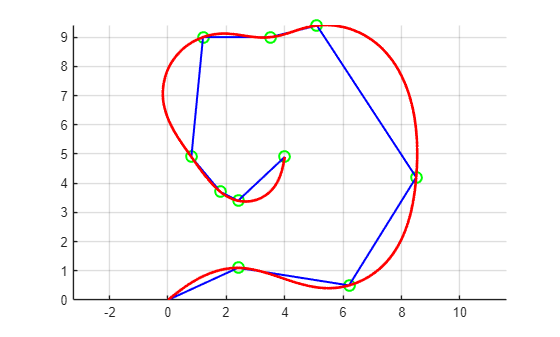

steps = steps_start;
for ii = 2:length(steps_end)

    startA = steps(2, ii);
    deltaA = wrapToPi(steps_end(2, ii) - startA);

    rad_sweep = startA + linspace(0, deltaA, N);

    for jj = 1:N
        steps(2, ii:end) = rad_sweep(jj);
        cartesian_mod = polarSteps2cart([0 0], steps);
        % calling BPV itteratively
        cities = cartesian_mod(:, 2:end);
        start = [0; 0];
        options = bvpset('RelTol',1e-4,'AbsTol',1e-6,'NMax',500);
        sol = bvp4c(@(t,s,times)ODEMain(t,s,times,r), @(so,sf,times)bcfunc(so,sf, r, cities, start, times), sol, options);

        clf; hold on;

        % 1) Plot cities (green circles)
        plot(cities(1,:), cities(2,:), 'og', 'MarkerSize', 8, 'LineWidth', 1.5);

        % 2) Plot polygonal path (blue)
        plot(cartesian_mod(1,:), cartesian_mod(2,:), 'b-', 'LineWidth', 1.5);

        % 3) Plot ALL BVP arcs (red)
        m = length(sol.parameters);   % number of arcs
        for kk = 1:m
            xk = sol.y(1 + 8*(kk-1), :);
            yk = sol.y(2 + 8*(kk-1), :);
            plot(xk, yk, 'r-', 'LineWidth', 2);
        end

        axis equal
        % axis([0 5 0 4])
        grid on
        drawnow
        hold off

    end
end

## "r" Hometopy

All the rotational homotopy steps assume a constant value of the arbitrary control $r$. During this second stage of the homotopy, the value of $r$ is iterated and increased to a more reasonable magnitude. The final value of $r$ was chosen semi-arbitrarily as a number large enough that further increases produced no meaningful improvement in the final cost.

It should also be noted that an animation of both homotopy steps was created for personal interest and to help visualize and track the progression of the homotopy process.

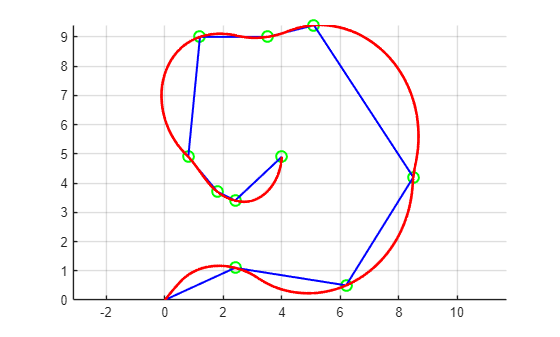

for r = linspace(1.5, 100, 100)
    sol = bvp4c(@(t,s,times)ODEMain(t,s,times,r), @(so,sf,times)bcfunc(so,sf, r, cities, start, times), sol, options);

    figure(2)
    clf; hold on;

    % 1) Plot cities (green circles)
    plot(cities(1,:), cities(2,:), 'og', 'MarkerSize', 8, 'LineWidth', 1.5);

    % 2) Plot polygonal path (blue)
    plot(cartesian_mod(1,:), cartesian_mod(2,:), 'b-', 'LineWidth', 1.5);

    % 3) Plot ALL BVP arcs (red)
    m = length(sol.parameters);   % number of arcs
    for kk = 1:m
        xk = sol.y(1 + 8*(kk-1), :);
        yk = sol.y(2 + 8*(kk-1), :);
        plot(xk, yk, 'r-', 'LineWidth', 2);
    end

    axis equal
    % axis([0 5 0 4])
    grid on
    drawnow
    hold off
    title(sprintf('r = %.3f   |   Total Time = %.3f', r, sum(sol.parameters)));
end

## Hometopy Supporting Functions

Here are the supporting functions for the homotopy steps, which include the coordinate transformation routines and a function that accelerates the homotopy by rotating the cities only in the direction requiring the least “turning.” This allows for more stable convergence by preventing rotations larger than $\pi$ radians. Larger rotations could lead to cusp-like solutions, which seemed unlikely for the sequence we selected.

% helps avoid circuling a position multiple times
function ang = wrapToPi(ang)
ang = mod(ang + pi, 2*pi) - pi;
end

% gives polar coordinates from point to point
function steps = polarSteps(points)
% points is 2×N: [x; y]
% returns 2×(N-1): [distance; angle]

x = points(1,:);
y = points(2,:);

N = size(points,2);
steps = zeros(2, N-1);

for i = 1:N-1
    dx = x(i+1) - x(i);
    dy = y(i+1) - y(i);

    dist  = sqrt(dx^2 + dy^2);   % radial distance between points
    angle = atan2(dy, dx);       % direction to travel

    steps(:, i) = [dist; angle];
end
end

% gives the cartesian coordinates given the polar steps that need to be
% taken to go from point to point. the initial position does need to be
% given though.
function points = polarSteps2cart(startPoint, steps)
% startPoint : [x0; y0] column vector (2×1)
% steps      : 2×N matrix, each column = [distance; angle]
% returns    : 2×(N+1) matrix of Cartesian coordinates

N = size(steps, 2);
points = zeros(2, N+1);

% Set starting point
points(:,1) = startPoint;

for i = 1:N
    d = steps(1,i);      % distance to next point
    a = steps(2,i);      % angle (radians)

    % Convert polar step→local cartesian displacement
    dx = d * cos(a);
    dy = d * sin(a);

    % accumulate
    points(:, i+1) = points(:, i) + [dx; dy];
end
end